% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 36);

% Specify sheet and range
opts.Sheet = "Planilha1";
opts.DataRange = "A41:AJ10981";

% Specify column names and types
opts.VariableNames = ["ScanSweepTime_Sec_", "ScanNumber", "x101Time_Sec_", "x101__C_", "x102Time_Sec_", "x102__C_", "x103Time_Sec_", "x103__C_", "x104Time_Sec_", "x104__C_", "x105Time_Sec_", "x105__C_", "x106Time_Sec_", "x106__C_", "x107Time_Sec_", "x107__C_", "x108Time_Sec_", "x108__C_", "x109Time_Sec_", "x109__C_", "x110Time_Sec_", "x110__C_", "x111Time_Sec_", "x111__C_", "x112Time_Sec_", "x112__C_", "x113Time_Sec_", "x113__C_", "x114Time_Sec_", "x114__C_", "x115Time_Sec_", "x115__C_", "x116Time_Sec_", "x116__C_", "x117Time_Sec_", "x117_Vac_"];
opts.VariableTypes = ["datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double", "datetime", "double"];

% Import the data
data = readtimetable("C:\Users\PEDRO\OneDrive\Documentos\Insper\2024.2\TransCal\Projeto 1\TransCal_Projeto1\data.xlsx", opts, "UseExcel", false, "RowTimes", "ScanSweepTime_Sec_");

% Clear temporary variables
clear opts

% Display results
data

data = 10941×35 timetable
     ScanSweepTime_Sec_     ScanNumber       x101Time_Sec_        x101__C_       x102Time_Sec_        x102__C_       x103Time_Sec_        x103__C_       x104Time_Sec_        x104__C_       x105Time_Sec_        x105__C_       x106Time_Sec_        x106__C_       x107Time_Sec_        x107__C_       x108Time_Sec_        x108__C_       x109Time_Sec_        x109__C_       x110Time_Sec_        x110__C_       x111Time_Sec_        x111__C_       x112Time_Sec_        x112__C_       x113Time_Sec_        x113__C_<

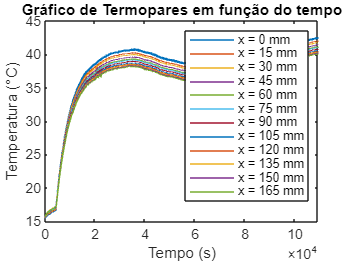

% Gráfico 0.1
time = data.x101Time_Sec_;
tamanho_time = length(time);
vetor_time = 10 * (0:tamanho_time-1);
termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_time, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Tempo (s)');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares em função do tempo');

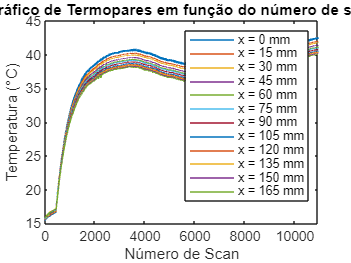

% Gráfico 0.2
vetor_num_scan = data.ScanNumber;
termopares = {data.x102__C_, data.x103__C_, data.x104__C_, data.x105__C_, data.x106__C_, data.x107__C_, data.x108__C_, data.x109__C_, data.x110__C_, data.x111__C_, data.x112__C_, data.x113__C_};
legendas = {'x = 0 mm', 'x = 15 mm', 'x = 30 mm', 'x = 45 mm', 'x = 60 mm', 'x = 75 mm', 'x = 90 mm', 'x = 105 mm', 'x = 120 mm', 'x = 135 mm', 'x = 150 mm', 'x = 165 mm'};

for i = 1:length(termopares)
    plot(vetor_num_scan, termopares{i});  
    hold on;  
end

hold off;  
legend(legendas);
xlabel('Número de Scan');
ylabel('Temperatura (°C)');
title('Gráfico de Termopares em função do número de scan');

#### Intervalo do regime permanente identificado: Scan 6000 a 8000

% Filtrar as linhas que compõem o intervalo de regime permanente
regime_permanente = data((data.ScanNumber >= 6000) & (data.ScanNumber <= 8000), :);

% Selecionar as temperaturas não-NaN no intervalo filtrado
ind = ~isnan(regime_permanente.x101__C_);
Tamb_col = regime_permanente.x101__C_(ind);

% Calcular a temperatura média ambiente no intervalo
Tmamb = mean(Tamb_col);

% Calculando a temperatura média na aleta no regime permanente
Tm_aleta = 0;
termopares = {regime_permanente.x103__C_, regime_permanente.x104__C_, regime_permanente.x105__C_, regime_permanente.x106__C_, regime_permanente.x107__C_, regime_permanente.x108__C_, regime_permanente.x109__C_, regime_permanente.x110__C_, regime_permanente.x111__C_, regime_permanente.x112__C_, regime_permanente.x113__C_};
Tm_x = [0,0,0,0,0,0,0,0,0,0,0];

for i = 1: length(termopares)
    Tm_x(i) = mean(termopares{i});   % Media de cada posicao da aleta, durante reg perm
    Tm_aleta = Tm_aleta + mean(termopares{i});
end

Tm_aleta = Tm_aleta/11;

% Temperatura de filme
Tf = (Tm_aleta + Tmamb)/2;

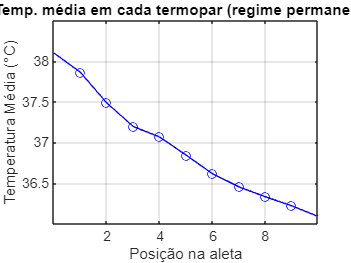

% Gráfico 1
posicoes = zeros(1,11);
init = 16;
for i = 1:length(Tm_x)
    posicoes(i) = i-1;
end

plot(posicoes, Tm_x, '-ob');
title("Gráfico 1");
xlabel('Posição na aleta');
ylabel('Temperatura Média (°C)');
grid on;
title('Temp. média em cada termopar (regime permanente)');

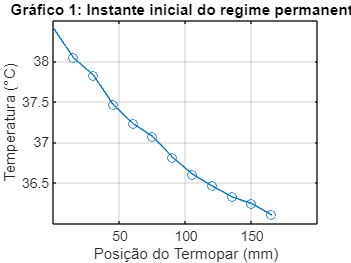

% Gráfico 1: Utilizando o instante de início do regime permanente para o gráfico 1
temperaturas_inicio_regime = data(data.ScanNumber == 6000, :);
termopares_posicao = 0:15:165;
valores_termopares = zeros(1, 12);

for i = 102:113
    col_name = sprintf('x%d__C_', i); 
    valores_termopares(i - 101) = temperaturas_inicio_regime.(col_name);
end

plot(termopares_posicao, valores_termopares, '-o');  
title("Gráfico 1: Instante inicial do regime permanente");
xlabel('Posição do Termopar (mm)');
ylabel('Temperatura (°C)');
grid on;

% Calculando a condutividade do material no regime permanente (k), usando:
x0 = 37.78;
f_x0 = 155.68;

x1 = 51.67;
f_x1 = 156.88;

% Interpolacao de Newton:
%      f1(x) = f(x0) + (( f(x1) - f(x0) )   /  ( x1 - x0 )) * ( x - x0 )
k_Tf = f_x0 + ( ( f_x1 - f_x0 ) / (x1 - x0)) * (Tf - x0)

k_Tf = 154.7420

r = 0.012

r = 0.0120

Atr = pi*r^2

Atr = 4.5239e-04

L = 0.2

L = 0.2000

Tb = 38.5

Tb = 38.5000

Tamb = 16

Tamb = 16

h = 2 % Slide Aula 6

h = 2

P = 2*pi*r

P = 0.0754

m = sqrt((h*P)/(k_Tf*Atr))

m = 1.4677

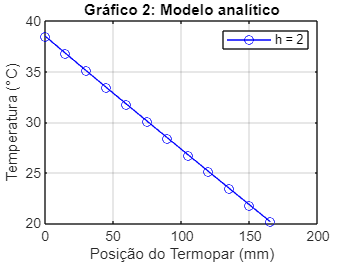


valores_termopares_analitico = zeros(size(termopares_posicao));

for i = 1:length(termopares_posicao)
    position = termopares_posicao(i);
    valores_termopares_analitico(i) = (Tb-Tamb)*((cosh(m*(L - (position/1000))) +  (h/m*k_Tf)*sinh(m*(L - (position/1000))))/(cosh(m*L) + (h/m*k_Tf)*sinh(m*L))) + Tamb;
end

plot(termopares_posicao, valores_termopares_analitico, "-ob");
title("Gráfico 2: Modelo analítico");
xlabel('Posição do Termopar (mm)');
ylabel('Temperatura (°C)');
legend({'h = 2'});
grid on;